clear,clc,warning('off')

I1

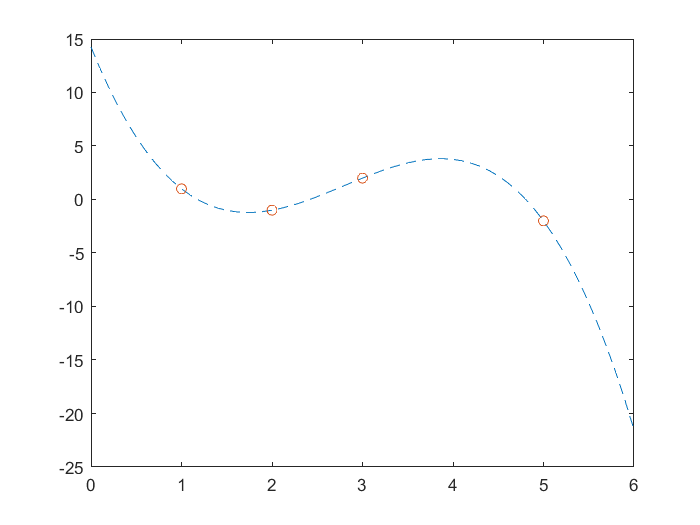

X=[1,2,3,5]';
Y=[1,-1,2,-2]';
x=[0:0.1:6];

[p, S] = polyfit(X, Y, 3);
[Y_fit] = polyval(p, x, S);
plot(x, Y_fit, "--")
hold on;
plot(X,Y,'o')
hold off;


vander(X)

ans =      1     1     1     1
     8     4     2     1
    27     9     3     1
   125    25     5     1


V=macierz_vandermonde(X)

V =      1     1     1     1
     8     4     2     1
    27     9     3     1
   125    25     5     1


w=linsolve(V,Y)

w =    -1.0417
    8.7500
  -20.9583
   14.2500


polyval(w,X)

ans =     1.0000
   -1.0000
    2.0000
   -2.0000


I2, I4, I7

X=[1:20]';
Y=randi([-2,2],20,1);
n0=4;
n=[n0:20];
sredniKwadratBladV=zeros(1,length(n));
sredniKwadratBladL=zeros(1,length(n));
sredniKwadratBladLWzor=zeros(1,length(n));
sredniKwadratBladRTr=zeros(1,length(n));

wskUwarV=zeros(1,length(n));
wskUwarL=zeros(1,length(n));

for i=1:length(n)
    V=macierz_vandermonde(X(1:i+n0-1,1));
    p=linsolve(V,Y(1:i+n0-1,1));
    tempV=0;
    tempL=0;
    tempLWzor=0;
    tempRTr=0;
    for j=1:i+n0-1
        tempV=tempV+(Y(j,1)-polyval(p,X(j,1)))^2;
        tempL=tempL+(Y(j,1)-polyval(wielomian_interpolacyjny_lagrangea(X,Y),X(j,1)))^2;
        
          nn = i+n0-1;
          y = 0;
        for ii = 1:nn
            temp=1;
            for k=1:nn
                if k~=ii
                    temp=temp*(X(j,1)-X(k,1))/(X(ii,1)-X(k,1));
                end
            end
            y = y + Y(ii) * temp;
        end
        tempLWzor=tempLWzor+(Y(j,1)-y)^2;
        tempRTr=tempRTr+(Y(j,1)-wartosc_rodzina_trojkatna(X,Y,X(j,1)))^2
    end
    sredniKwadratBladV(i)=tempV/(i+n0-1);
    sredniKwadratBladL(i)=tempL/(i+n0-1);
    sredniKwadratBladLWzor(i)=tempLWzor/(i+n0-1);
    sredniKwadratBladRTr(i)=tempRTr/(i+n0-1);
    wskUwarV(i)=norm(V)*(norm(inv(V)));
end

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 3.5038e-26

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 3.5038e-26

tempRTr = 1.1582e-25

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 3.5038e-26

tempRTr = 1.1582e-25

tempRTr = 1.3218e-25

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 3.5038e-26

tempRTr = 1.1582e-25

tempRTr = 1.3218e-25

tempRTr = 6.9945e-25

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 3.5038e-26

tempRTr = 1.1582e-25

tempRTr = 1.3218e-25

tempRTr = 6.9945e-25

tempRTr = 1.4633e-24

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 3.5038e-26

tempRTr = 1.1582e-25

tempRTr = 1.3218e-25

tempRTr = 6.9945e-25

tempRTr = 1.4633e-24

tempRTr = 1.9344e-22

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 3.5038e-26

tempRTr = 1.1582e-25

tempRTr = 1.3218e-25

tempRTr = 6.9945e-25

tempRTr = 1.4633e-24

tempRTr = 1.9344e-22

tempRTr = 6.3579e-22

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 3.5038e-26

tempRTr = 1.1582e-25

tempRTr = 1.3218e-25

tempRTr = 6.9945e-25

tempRTr = 1.4633e-24

tempRTr = 1.9344e-22

tempRTr = 6.3579e-22

tempRTr = 2.4366e-20

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 3.5038e-26

tempRTr = 1.1582e-25

tempRTr = 1.3218e-25

tempRTr = 6.9945e-25

tempRTr = 1.4633e-24

tempRTr = 1.9344e-22

tempRTr = 6.3579e-22

tempRTr = 2.4366e-20

tempRTr = 3.2473e-20

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 3.5038e-26

tempRTr = 1.1582e-25

tempRTr = 1.3218e-25

tempRTr = 6.9945e-25

tempRTr = 1.4633e-24

tempRTr = 1.9344e-22

tempRTr = 6.3579e-22

tempRTr = 2.4366e-20

tempRTr = 3.2473e-20

tempRTr = 3.2526e-20

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 3.5038e-26

tempRTr = 1.1582e-25

tempRTr = 1.3218e-25

tempRTr = 6.9945e-25

tempRTr = 1.4633e-24

tempRTr = 1.9344e-22

tempRTr = 6.3579e-22

tempRTr = 2.4366e-20

tempRTr = 3.2473e-20

tempRTr = 3.2526e-20

tempRTr = 2.7732e-19

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 0

tempRTr = 5.0487e-29

tempRTr = 1.0097e-28

tempRTr = 9.0877e-28

tempRTr = 3.5038e-26

tempRTr = 1.1582e-25

tempRTr = 1.3218e-25

tempRTr = 6.9945e-25

tempRTr = 1.4633e-24

tempRTr = 1.9344e-22

tempRTr = 6.3579e-22

tempRTr = 2.4366e-20

tempRTr = 3.2473e-20

tempRTr = 3.2526e-20

tempRTr = 2.7732e-19

tempRTr = 2.2289e-18

%whos

  Name                         Size            Bytes  Class     Attributes

  S                            1x1               648  struct              
  V                           20x20             3200  double              
  X                           20x1               160  double              
  Y                           20x1               160  double              
  Y_fit                        1x61              488  double              
  ans                          4x1                32  double              
  i                            1x1                 8  double              
  ii                           1x1                 8  double              
  j                            1x1                 8  double              
  k                            1x1                 8  double              
  n                            1x17              136  double              
  n0                           1x1                 8  double              
  nn                    

podsumowanie=[n' sredniKwadratBladV' wskUwarV' sredniKwadratBladL' sredniKwadratBladLWzor' sredniKwadratBladRTr'];

I2

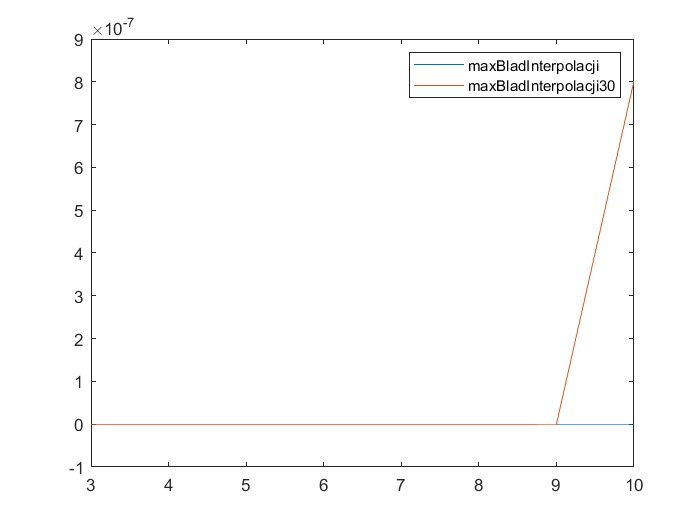

X=[1,2,3,4,5,6,7,8,9,10]';
X30=[1,2,3,4,5,6,7,8,9,39]';
Y=randi([-2,2],10,1);
n0=3;
n=[n0:10];
maxBladInterpolacji=zeros(1,length(n));
maxBladInterpolacji30=zeros(1,length(n));
for i=1:length(n)
    V=macierz_vandermonde(X(1:i+n0-1,1));
    V30=macierz_vandermonde(X30(1:i+n0-1,1));
    p=linsolve(V,Y(1:i+n0-1,1));
    p30=linsolve(V30,Y(1:i+n0-1,1));
    maxBladInterpolacji(i)=max(Y(1:i+n0-1,1)-polyval(p,X(1:i+n0-1,1)));
    maxBladInterpolacji30(i)=max(Y(1:i+n0-1,1)-polyval(p30,X30(1:i+n0-1,1)));
end

plot(n,maxBladInterpolacji)
hold on;
plot(n,maxBladInterpolacji30)
legend("maxBladInterpolacji","maxBladInterpolacji30");
hold off;

l3

X=[1,2,3,5]';
Y=[1,-1,2,-2]';
x=[0:0.1:6];
interpolacja_lagrange(X,Y,x)

ans =    14.2500   12.2406   10.4000    8.7219    7.2000    5.8281    4.6000    3.5094    2.5500    1.7156    1.0000    0.3969   -0.1000   -0.4969   -0.8000   -1.0156   -1.1500   -1.2094   -1.2000   -1.1281   -1.0000   -0.8219   -0.6000   -0.3406   -0.0500    0.2656    0.6000    0.9469    1.3000    1.6531    2.0000    2.3344    2.6500    2.9406    3.2000    3.4219    3.6000    3.7281    3.8000    3.8094    3.7500    3.6156    3.4000    3.0969    2.7000    2.2031    1.6000    0.8844    0.0500   -0.9094


I5

[p]=wielomian_interpolacyjny_lagrangea(X,Y)

p =    -1.0417    8.7500  -20.9583   14.2500


polyval(p,x)

ans =    14.2500   12.2406   10.4000    8.7219    7.2000    5.8281    4.6000    3.5094    2.5500    1.7156    1.0000    0.3969   -0.1000   -0.4969   -0.8000   -1.0156   -1.1500   -1.2094   -1.2000   -1.1281   -1.0000   -0.8219   -0.6000   -0.3406   -0.0500    0.2656    0.6000    0.9469    1.3000    1.6531    2.0000    2.3344    2.6500    2.9406    3.2000    3.4219    3.6000    3.7281    3.8000    3.8094    3.7500    3.6156    3.4000    3.0969    2.7000    2.2031    1.6000    0.8844    0.0500   -0.9094


I6

wielomian_interpolacyjny_rodzina_trojkatna(X,Y)

ans =     1.0000
   -2.0000
    2.5000
   -1.0417


[Y_fit]=wartosc_rodzina_trojkatna(X,Y,x);
plot(x,Y_fit,'--')
hold on;
plot(X,Y,'o')
hold off;

I9

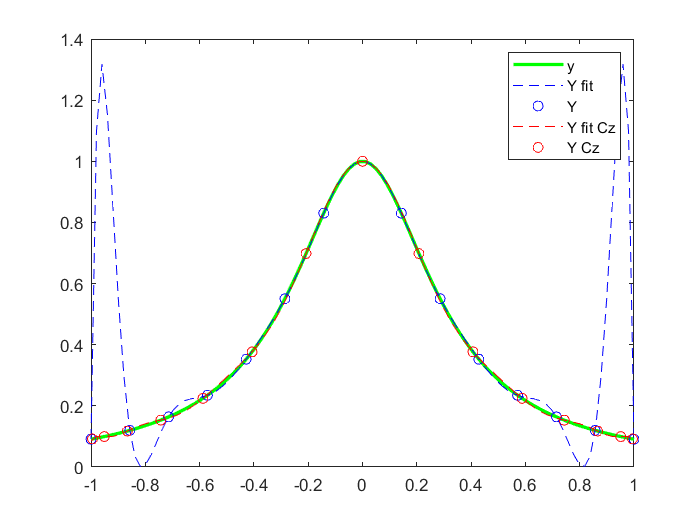

f=@(x) 1./(1+10*x.^2);
x=linspace(-1,1,100);
y=f(x);

n=15;
X=linspace(-1,1,n);
X_Cz=wezlyCzebyszewa(n-1);

Y=f(X);
Y_Cz=f(X_Cz);


[p, S] = polyfit(X, Y, n-1);
[p_Cz, S_Cz] = polyfit(X_Cz, Y_Cz, n-1);

[Y_fit] = polyval(p, x, S);
[Y_Cz_fit] = polyval(p_Cz, x, S_Cz);

plot(x,y,'g','LineWidth',2);
hold on;
plot(x, Y_fit, "b--")
plot(X,Y,'bo')

plot(x, Y_Cz_fit, "r--")
plot(X_Cz,Y_Cz,'ro')
hold off;

legend('y','Y fit','Y','Y fit Cz','Y Cz')

Średni błąd:

sredniBlad=0;
sredniBlad_Cz=0;
for i=1:100
    sredniBlad=sredniBlad+Y_fit(i)-y(i);
    sredniBlad_Cz=sredniBlad_Cz+Y_Cz_fit(i)-y(i);
end
sredniBlad=sredniBlad/100

sredniBlad = 0.0838

sredniBlad_Cz=sredniBlad_Cz/100

sredniBlad_Cz = 1.6488e-05

I10

f=@(x) sign(x);
zakresL=-5;
zakresP=5;
stopnie=[3:6,10,15,20]

stopnie =      3     4     5     6    10    15    20


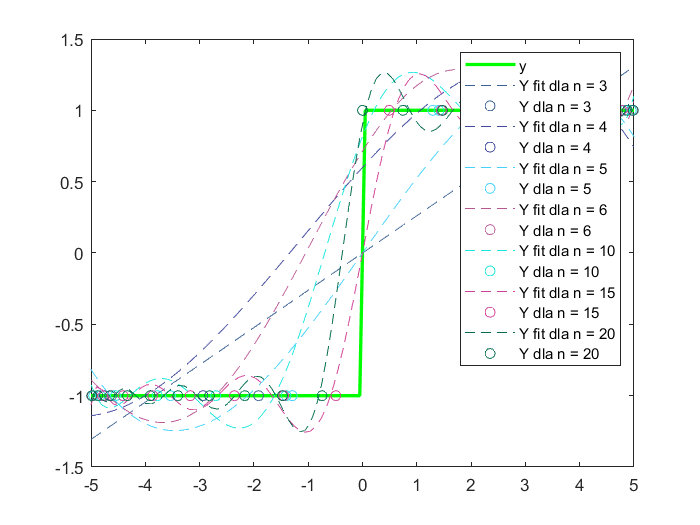

x=linspace(zakresL,zakresP,100);
y=f(x);
plot(x,y,'g','LineWidth',2);
hold on;
legend_names=["y"];
Y_fit=zeros(100,max(stopnie));
for n=stopnie
X=wezlyCzebyszewa(n)*5;
Y=f(X);
[p, S] = polyfit(X, Y, n-1);
[Y_fit(:,n)] = polyval(p, x, S);
randomRGB=rand(1,3);
plot(x, Y_fit(:,n), "--",'color',randomRGB)
plot(X,Y,'o','color',randomRGB)
legend_names(end+1)="Y fit dla n = "+n;
legend_names(end+1)="Y dla n = "+n;
end
hold off;
legend(legend_names);

for n=stopnie
    disp("Dla n = "+string(n)+" maksymalny blad = "+string(max(Y_fit(:,n)-y')));
end

Dla n = 3 maksymalny blad = 0.9868
Dla n = 4 maksymalny blad = 1.5787
Dla n = 5 maksymalny blad = 0.97271
Dla n = 6 maksymalny blad = 1.6835
Dla n = 10 maksymalny blad = 1.7685
Dla n = 15 maksymalny blad = 0.89926
Dla n = 20 maksymalny blad = 1.806
